open_system("Articulated_arm_real_proportions");



test

path_simu = 'Articulated_arm_real_proportions';

set_param(path_simu, 'SolverType', 'Fixed-step');   % fixed-step solver
%before : set_param(path_simu, 'FixedStep', '0.001');         % time step in sec
set_param(path_simu, 'FixedStep', '0.001'); 
%before set_param(path_simu, 'StopTime', '100'); 
set_param(path_simu, 'StopTime', '10');             % simulate time

Sweep Value

K1vals = linspace(0.04, 0.08, 5);
K2vals = linspace(0.4,  0.8,  5);
K3vals = linspace(0.4,  0.8,  5);
delta_theta = linspace(0.5, 2.0, 5);


f_min = [2 2 2];
f_max = [20 20 20];
frac  = [0.8 0.8 0.8];

nbins = 10;
frac_thresh = 0.7;

counter = 0;

nSim = numel(K1vals)*numel(K2vals)*numel(K3vals)*numel(delta_theta);

% stockage FFT
FFT_store = cell(nSim,3);
F_store   = cell(nSim,3);


for i1 = 1:numel(K1vals)
for i2 = 1:numel(K2vals)
for i3 = 1:numel(K3vals)
for i4 = 1:numel(delta_theta)

    set_param([path_simu '/Gain3'],  'Gain', num2str(K1vals(i1)));
    set_param([path_simu '/Gain9'],  'Gain', num2str(K1vals(i1)));
    set_param([path_simu '/Gain4'],  'Gain', num2str(K2vals(i2)));
    set_param([path_simu '/Gain10'], 'Gain', num2str(K2vals(i2)));
    set_param([path_simu '/Gain5'],  'Gain', num2str(K3vals(i3)));
    set_param([path_simu '/Gain8'],  'Gain', num2str(K3vals(i3)));
    set_param([path_simu '/delta_angle_deg_const'], 'Value', num2str(delta_theta(i4)));

    simOut = sim(path_simu);
    logsout = simOut.logsout;

    theta_1_signal = logsout.getElement('theta_1');
    theta_2_signal = logsout.getElement('theta_2');
    theta_3_signal = logsout.getElement('theta_3');

    theta_1_array_prev = squeeze(theta_1_signal.Values.Data);
    theta_2_array_prev = squeeze(theta_2_signal.Values.Data);
    theta_3_array_prev = squeeze(theta_3_signal.Values.Data);

    theta_1_array = theta_1_array_prev(:,1);
    theta_2_array = theta_2_array_prev(:,1);
    theta_3_array = theta_3_array_prev(:,1);

    if counter == 0
        time_array = theta_1_signal.Values.Time;
        N = numel(time_array);

        dt = time_array(2) - time_array(1);
        Fs = 1/dt;

        f = (0:N-1)*(Fs/N);
        f_pos = f(1:floor(N/2));
    end

    counter = counter + 1;

    signals = {theta_1_array, theta_2_array, theta_3_array};

    for t = 1:3

        signal = signals{t};

        signal = signal(:);

        Y = fft(signal);
        Y(1) = 0;

        P = abs(Y)/N;
        P = P(1:floor(N/2));

        idx = (f_pos >= f_min(t)) & (f_pos <= f_max(t));

        FFT_store{counter,t} = P(idx);
        F_store{counter,t}   = f_pos(idx);
    end

end
end
end
end

-------------------------
end = -0.039662
end = 0.000000
end = 0.275693
-------------------------
best_next_theta_1_pos = 1.000000
best_next_theta_2_pos = 1.000000
best_next_theta_3_pos = 1.000000
best_next_theta_1_neg = 0.000000
best_next_theta_2_neg = 0.000000
best_next_theta_3_neg = 0.000000
-------------------------
end = -0.049113
end = 0.000000
end = 0.283457
-------------------------
best_next_theta_1_pos = 1.000000
best_next_theta_2_pos = 1.000000
best_next_theta_3_pos = 1.000000
best_next_theta_1_neg = 0.000000
best_next_theta_2_neg = 0.000000
best_next_theta_3_neg = 0.000000
-------------------------
end = -0.059164
end = 0.000000
end = 0.290911
-------------------------
best_next_theta_1_pos = 1.000000
best_next_theta_2_pos = 1.000000
best_next_theta_3_pos = 1.000000
best_next_theta_1_neg = 0.000000
best_next_theta_2_neg = 0.000000
best_next_theta_3_neg = 0.000000
-------------------------
end = -0.069591
end = 0.000000
end = 0.297969
-------------------------
best_next_thet

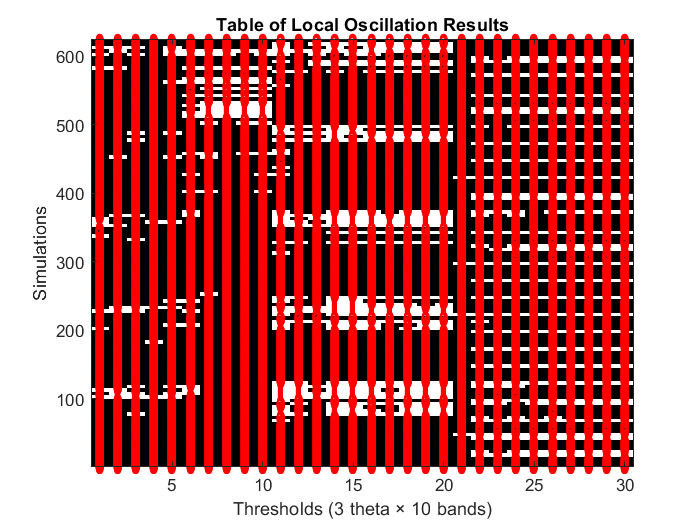

globalMax = zeros(3, nbins);

for s = 1:nSim
    for t = 1:3

        P_filt = FFT_store{s,t};
        f_filt = F_store{s,t};

        if isempty(P_filt)
            continue;
        end

        edges = linspace(f_min(t), f_max(t), nbins+1);

        for b = 1:nbins

            bin_idx = (f_filt >= edges(b)) & (f_filt < edges(b+1));
            bin_data = P_filt(bin_idx);

            if ~isempty(bin_data)
                globalMax(t,b) = max(globalMax(t,b), max(bin_data));
            end
        end
    end
end

globalThreshold = frac(:) .* globalMax;


oscTable = zeros(nSim,30);

for s = 1:nSim

    col = 1;

    for t = 1:3

        P_filt = FFT_store{s,t};
        f_filt = F_store{s,t};

        edges = linspace(f_min(t), f_max(t), nbins+1);

        for b = 1:nbins

            bin_idx = (f_filt >= edges(b)) & (f_filt < edges(b+1));
            bin_data = P_filt(bin_idx);

            if ~isempty(bin_data)

                th = globalThreshold(t,b);

                if any(abs(bin_data - th) < 1e-12 | bin_data > th)
                    oscTable(s,col) = 1;
                end
            end

            col = col + 1;
        end
    end
end


isOscillating = zeros(nSim,1);

for s = 1:nSim
    nbZeros = sum(oscTable(s,:) == 0);

    if nbZeros >= nbins * 3 * frac_thresh
        isOscillating(s) = 0;
    else
        isOscillating(s) = 1;
    end
end






disp('Nombre simulations oscillantes :'); disp(sum(isOscillating));

Nombre simulations oscillantes :
   165




s = 1; 
theta_1 = theta_1_array

theta_1 =     1.3963
    1.3963
    1.3963
    1.3963
    1.3963
    1.3962
    1.3962
    1.3962
    1.3962
    1.3961


theta_2 = theta_2_array

theta_2 =          0
         0
         0
    0.0000
    0.0000
    0.0000
    0.0001
    0.0001
    0.0002
    0.0003


theta_3 = theta_3_array

theta_3 =    -2.4435
   -2.4435
   -2.4435
   -2.4435
   -2.4435
   -2.4435
   -2.4435
   -2.4435
   -2.4435
   -2.4435


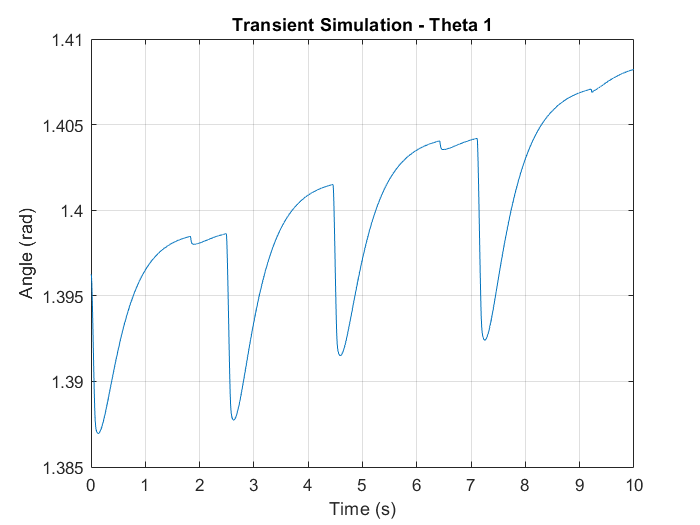

theta1 = squeeze(theta_1(:,1,1,1,1));
theta2 = squeeze(theta_2(:,1,1,1,1));
theta3 = squeeze(theta_3(:,1,1,1,1));

figure;
plot(time_array, theta1);
title('Transient Simulation - Theta 1');
xlabel('Time (s)');
ylabel('Angle (rad)');
grid on;

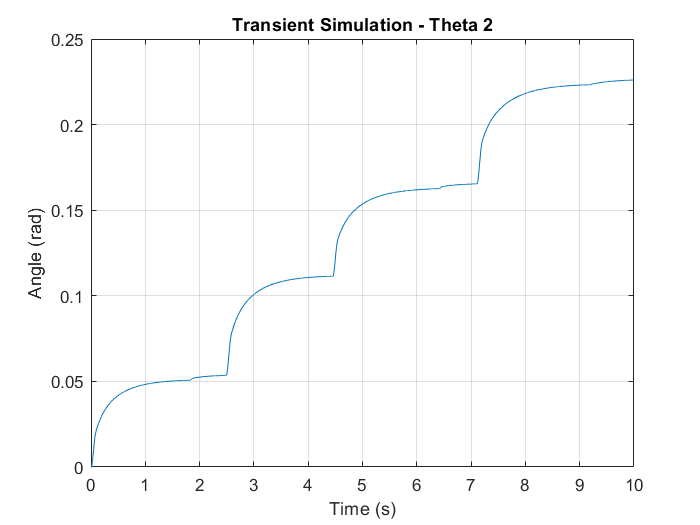


figure;
plot(time_array, theta2);
title('Transient Simulation - Theta 2');
xlabel('Time (s)');
ylabel('Angle (rad)');
grid on;

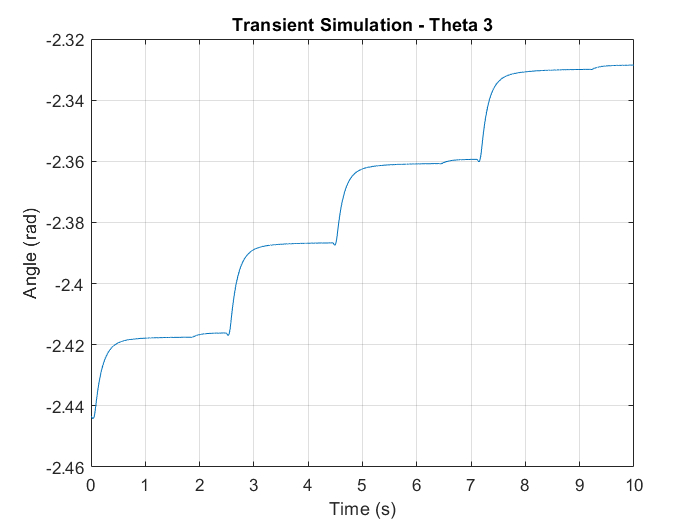


figure;
plot(time_array, theta3);
title('Transient Simulation - Theta 3');
xlabel('Time (s)');
ylabel('Angle (rad)');
grid on;

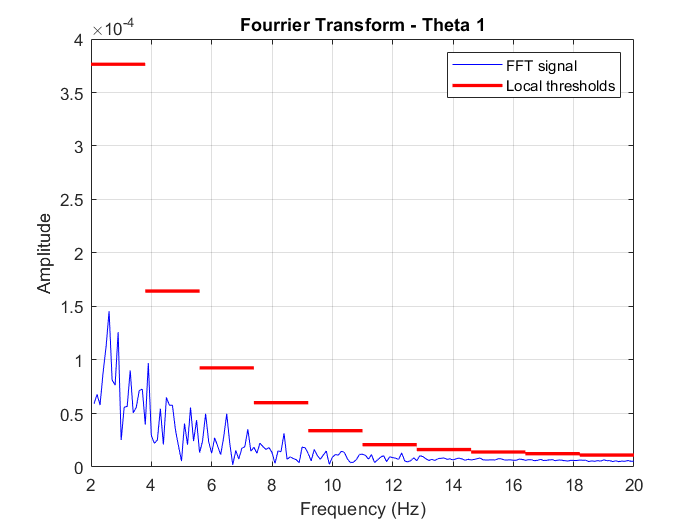

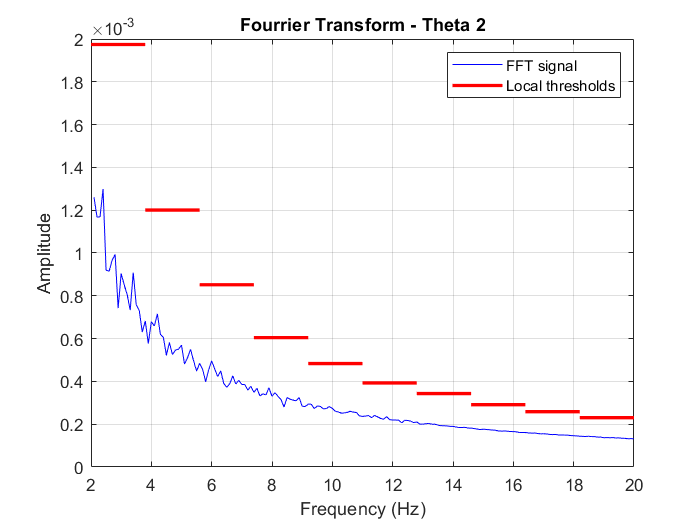

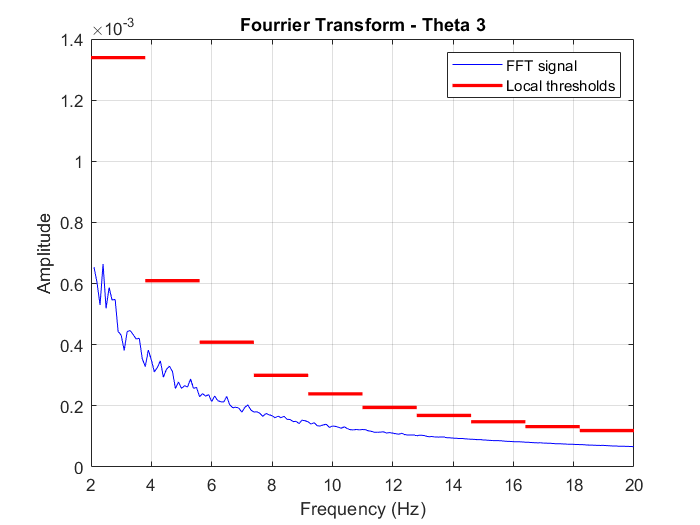


for t = 1:3
    
    P_filt = FFT_store{s,t};
    f_filt = F_store{s,t};

    figure;

    hFFT = plot(f_filt, P_filt, 'b'); hold on;
    
    title(['Fourrier Transform - Theta ', num2str(t)]);
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');
    grid on;

    edges = linspace(f_min(t), f_max(t), nbins+1);

    for b = 1:nbins
        th = globalThreshold(t,b);
        hTh = plot([edges(b) edges(b+1)], [th th], 'r', 'LineWidth', 2);
    end

    legend([hFFT, hTh], ...
        {'FFT signal', 'Local thresholds'}, ...
        'Location','northeast');

end

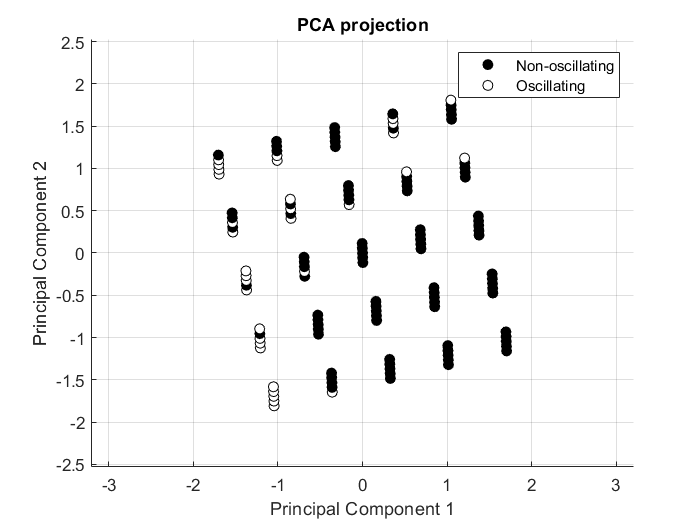





%nb_oscillating_per_sim = sum(oscTable,2)
%disp(nb_oscillating_per_sim)


%disp(size(theta_1));
%disp(size(theta_2));
%disp(size(theta_3));

result4D = zeros(numel(K1vals), numel(K2vals), numel(K3vals), numel(delta_theta));

counter = 1;

for i1 = 1:numel(K1vals)
for i2 = 1:numel(K2vals)
for i3 = 1:numel(K3vals)
for i4 = 1:numel(delta_theta)

    result4D(i1,i2,i3,i4) = isOscillating(counter);
    counter = counter + 1;

end
end
end
end


X = zeros(nSim,4);

counter = 1;

for i1 = 1:numel(K1vals)
for i2 = 1:numel(K2vals)
for i3 = 1:numel(K3vals)
for i4 = 1:numel(delta_theta)

    X(counter, :) = [K1vals(i1), K2vals(i2), K3vals(i3), delta_theta(i4)];
    counter = counter + 1;

end
end
end
end



X_mean = mean(X);
X_std  = std(X);

X_norm = (X - X_mean) ./ X_std;


% matrice covariance
C = cov(X_norm);

% valeurs propres et vecteurs propres
[V, D] = eig(C);

% trier par ordre décroissant
[eigvals, idx] = sort(diag(D), 'descend');
V = V(:, idx);

% garder les 2 principales composantes
V2 = V(:,1:2);

% projection des données
X_pca = X_norm * V2;


figure;
hold on;

hStable = [];
hOsc = [];

for i = 1:nSim

    if isOscillating(i) == 0
        hStable = plot(X_pca(i,1), X_pca(i,2), 'ko', 'MarkerFaceColor', 'k');
    else
        hOsc = plot(X_pca(i,1), X_pca(i,2), 'ko', 'MarkerFaceColor', 'w');
    end

end

xlabel('Principal Component 1');
ylabel('Principal Component 2');
title('PCA projection');
grid on;

legend([hStable, hOsc], ...
    {'Non-oscillating', 'Oscillating'}, ...
    'Location','northeast');


x_min = min(X_pca(:,1));
x_max = max(X_pca(:,1));
y_min = min(X_pca(:,2));
y_max = max(X_pca(:,2));

% marge 20%: ça adapte les axes
dx = 0.2 * (x_max - x_min);
dy = 0.2 * (y_max - y_min);

xlim([x_min - dx, x_max + dx]);
ylim([y_min - dy, y_max + dy]);

axis equal;


disp('--- PRINCIPAL COMPONENT 1 ---');

--- PRINCIPAL COMPONENT 1 ---


disp(['K1 weight = ', num2str(V2(1))]);

K1 weight = -0.002922


disp(['K2 weight = ', num2str(V2(2))]);

K2 weight = -0.97312


disp(['K3 weight = ', num2str(V2(3))]);

K3 weight = -0.23027


disp(['delta_theta weight = ', num2str(V2(4))]);

delta_theta weight = 0



disp(' ');


disp('--- PRINCIPAL COMPONENT 2 ---');

--- PRINCIPAL COMPONENT 2 ---


disp(['K1 weight = ', num2str(V2(1))]);

K1 weight = -0.002922


disp(['K2 weight = ', num2str(V2(2))]);

K2 weight = -0.97312


disp(['K3 weight = ', num2str(V2(3))]);

K3 weight = -0.23027


disp(['delta_theta weight = ', num2str(V2(4))]);

delta_theta weight = 0


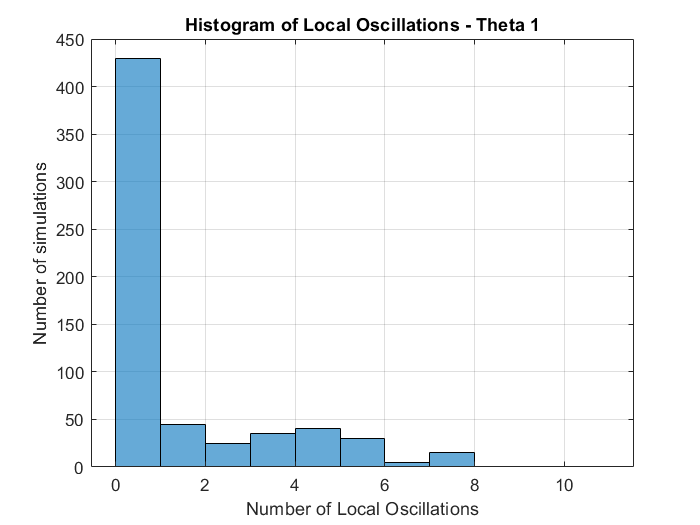


nbins = 10;

% stockage nombre de dépassements (par simulation et par theta)
count_theta = zeros(nSim, 3);

for s = 1:nSim
    for t = 1:3
        
        % indices colonnes correspondants dans oscTable
        col_start = (t-1)*nbins + 1;
        col_end   = t*nbins;
        
        % compter nombre de 1 (dépassements)
        count_theta(s,t) = sum(oscTable(s, col_start:col_end));
    end
end


figure;
histogram(count_theta(:,1), 0:nbins+1);
title('Histogram of Local Oscillations - Theta 1');
xlabel('Number of Local Oscillations');
ylabel('Number of simulations');
grid on;

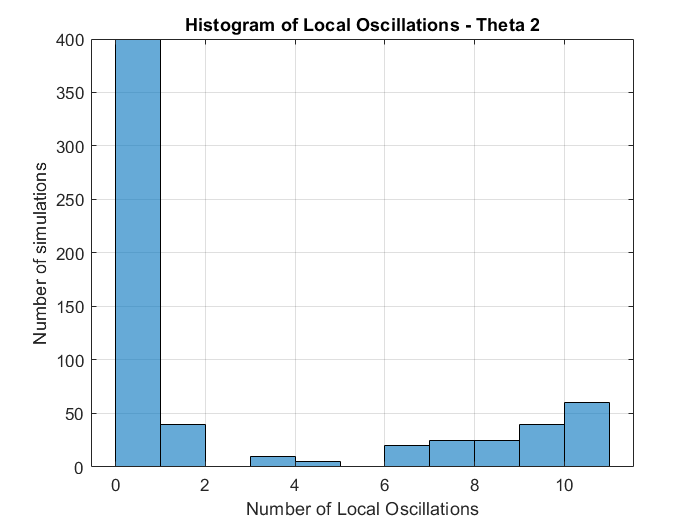



figure;
histogram(count_theta(:,2), 0:nbins+1);
title('Histogram of Local Oscillations - Theta 2');
xlabel('Number of Local Oscillations');
ylabel('Number of simulations');
grid on;

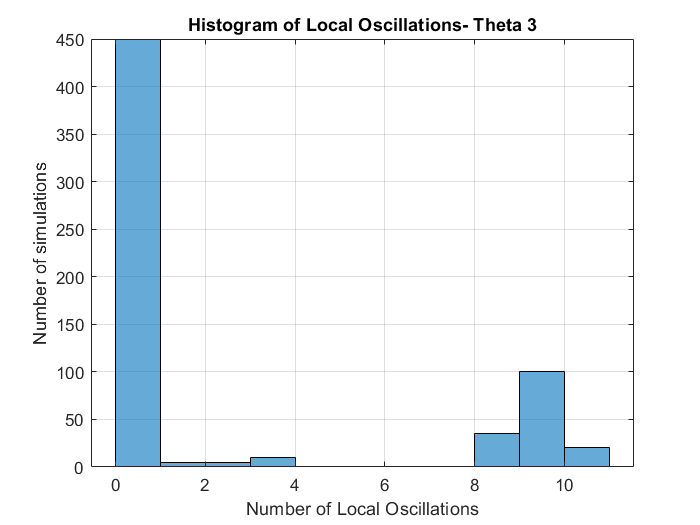



figure;
histogram(count_theta(:,3), 0:nbins+1);
title('Histogram of Local Oscillations- Theta 3');
xlabel('Number of Local Oscillations');
ylabel('Number of simulations');
grid on;




% nombre total d'oscillations (30 max)
total_osc = sum(oscTable, 2);

% trouver le minimum
[minOsc, bestIdx] = min(total_osc);

disp('------ BEST SIMULATION ------');

------ BEST SIMULATION ------


disp(['Simulation index: ', num2str(bestIdx)]);

Simulation index: 1


disp(['Number of local oscillations: ', num2str(minOsc)]);

Number of local oscillations: 0




% nombre total d'oscillations par simulation
total_osc = sum(oscTable, 2);

% trier par ordre croissant
[sortedOsc, sortedIdx] = sort(total_osc, 'ascend');

for k = 1:5

    idx = sortedIdx(k);
    nbOsc = sortedOsc(k);

    % retrouver les paramètres correspondants
    counter = 1;

    for i1 = 1:numel(K1vals)
    for i2 = 1:numel(K2vals)
    for i3 = 1:numel(K3vals)
    for i4 = 1:numel(delta_theta)

        if counter == idx
            K1_best = K1vals(i1);
            K2_best = K2vals(i2);
            K3_best = K3vals(i3);
            dt_best = delta_theta(i4);
        end

        counter = counter + 1;

    end
    end
    end
    end

    % affichage
    disp(['----- BEST RESULT #', num2str(k), ' -----']);
    disp(['Index: ', num2str(idx)]);
    disp(['Number of oscillations: ', num2str(nbOsc)]);
    disp(['K1 = ', num2str(K1_best)]);
    disp(['K2 = ', num2str(K2_best)]);
    disp(['K3 = ', num2str(K3_best)]);
    disp(['delta_theta = ', num2str(dt_best)]);
    disp(' ');

end

----- BEST RESULT #1 -----


Index: 1


Number of oscillations: 0


K1 = 0.04


K2 = 0.4


K3 = 0.4


delta_theta = 0.5


----- BEST RESULT #2 -----


Index: 2


Number of oscillations: 0


K1 = 0.04


K2 = 0.4


K3 = 0.4


delta_theta = 0.875


----- BEST RESULT #3 -----


Index: 3


Number of oscillations: 0


K1 = 0.04


K2 = 0.4


K3 = 0.4


delta_theta = 1.25


----- BEST RESULT #4 -----


Index: 4


Number of oscillations: 0


K1 = 0.04


K2 = 0.4


K3 = 0.4


delta_theta = 1.625


----- BEST RESULT #5 -----


Index: 5


Number of oscillations: 0


K1 = 0.04


K2 = 0.4


K3 = 0.4


delta_theta = 2
